## SimpleSharpRange is a template for future FunRobo Code

is an example of reading an analog Sharp IR Range sensor on an Arduino hook analog out from sensor into Pin A0, Vcc to 5VDC, and gnd to gnd.

Program collects range voltage data, plots it and is terminated by operator input

Oscar De La Garza & Olivia Jo Bradley 2021 Rev

clc
clear

**Set up robot control system **(code that runs once)

% Create arduno and arduino position servo ref-objects
    [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO('COM3');
% Turn on board LED on and off to signal program has started
    Blink(robotArduino,blinkLED,5);
    disp('Warning! Data Collection Active!')

Warning! Data Collection Active!


    
% Configure test loop to collect n data points
    nTests = input(['Enter the number of range test positions, followed by enter:']);
    clc;        % clear command window

% Create a variable to hold experimental position data
    positionData = zeros(nTests, 2);
    
r = rateControl(0.25);      % create a 0.25 hz loop rate
reset(r);    

**Run Robot Control Loop** (code that runs over and over)

controlFlag = 1;                    % creat a loop control
while(controlFlag < nTests+1)       % loop till ntests data captured
    
    % collect data from robot sensors
    rangeData = SENSE(robotArduino, rawRangeIn)
    THINK();                        % compute what robot should do next
    ACT();                          % command robot actuators
    
    % store experimental command versus actual data
    positionData(controlFlag,1) = input('Enter actual distance(cm): ');
    gtest = input('move Sharp to new range, type G, then hit ENTER', 's');
    positionData(controlFlag,2) = rangeData
    Blink(robotArduino,blinkLED,1);
    waitfor(r);                     % wait for loop cycle to complete
    controlFlag = controlFlag+1;    % increment loop
end

Sense


rangeData = 2.0039

positionData =    10.0000    2.0039
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Sense


rangeData = 2.4585

positionData =    10.0000    2.0039
   20.0000    2.4585
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Sense


rangeData = 1.9599

positionData =    10.0000    2.0039
   20.0000    2.4585
   30.0000    1.9599
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Sense


rangeData = 1.4858

positionData =    10.0000    2.0039
   20.0000    2.4585
   30.0000    1.9599
   40.0000    1.4858
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Sense


rangeData = 1.1975

positionData =    10.0000    2.0039
   20.0000    2.4585
   30.0000    1.9599
   40.0000    1.4858
   50.0000    1.1975
         0         0
         0         0
         0         0
         0         0
         0         0


Sense


rangeData = 0.9971

positionData =    10.0000    2.0039
   20.0000    2.4585
   30.0000    1.9599
   40.0000    1.4858
   50.0000    1.1975
   60.0000    0.9971
         0         0
         0         0
         0         0
         0         0


Sense


rangeData = 0.8407

positionData =    10.0000    2.0039
   20.0000    2.4585
   30.0000    1.9599
   40.0000    1.4858
   50.0000    1.1975
   60.0000    0.9971
   70.0000    0.8407
         0         0
         0         0
         0         0


Sense


rangeData = 0.7674

positionData =    10.0000    2.0039
   20.0000    2.4585
   30.0000    1.9599
   40.0000    1.4858
   50.0000    1.1975
   60.0000    0.9971
   70.0000    0.8407
   80.0000    0.7674
         0         0
         0         0


Sense


rangeData = 0.7771

positionData =    10.0000    2.0039
   20.0000    2.4585
   30.0000    1.9599
   40.0000    1.4858
   50.0000    1.1975
   60.0000    0.9971
   70.0000    0.8407
   80.0000    0.7674
   90.0000    0.7771
         0         0


Sense


rangeData = 0.5865

positionData =    10.0000    2.0039
   20.0000    2.4585
   30.0000    1.9599
   40.0000    1.4858
   50.0000    1.1975
   60.0000    0.9971
   70.0000    0.8407
   80.0000    0.7674
   90.0000    0.7771
  100.0000    0.5865


### Mission Data Processing

For many robot applucations, you will need to post-process the dat collected after the mission.

Here we will plot the measured versus actual range postions.

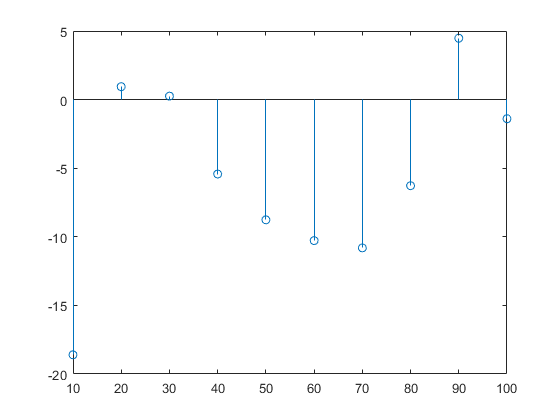

a = 171.1799;
b = -0.8929;
positionData(:,3) = a*exp(b*positionData(:,2));


stem(positionData(:,1), positionData(:,1)-positionData(:,3))

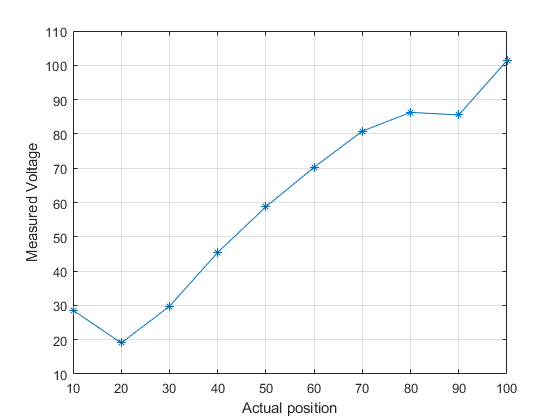


% Plot and store command postion data vs. actual postion
    figure(1)
    plot(positionData(:,1), positionData(:,3), '-*')
    xlabel('Actual position')
    ylabel('Measured Voltage')
    hold off
    grid 

    
    R = positionData(:,2);
    k = 0.42;
    y = 1./(R+k);
    figure(2)
    clf
    hold on
    plot(positionData(:,2),y, '*')
    customFit = fittype("m*x+b");
    f = fit(positionData(:,2),y,customFit);

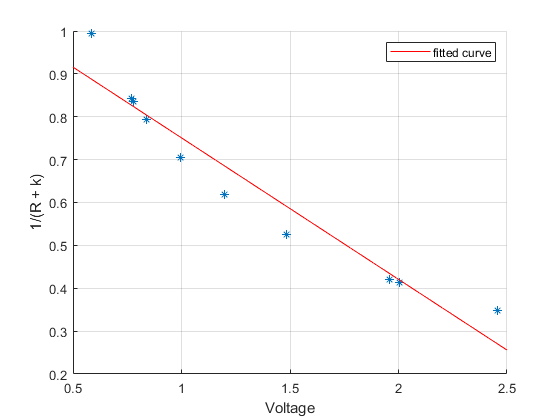

    
    plot(f)
    hold off
    xlabel('Voltage')
    ylabel('1/(R + k)')
    grid

### Clean shut down

Finally, with most embeded robot controllers, its good practice to put

all actuators into a safe position and then release all control objects and shut down all communication

paths. This keeps the systems from jamming when you want to run again.

% Stop program and clean up the connectino to the Ardunio when no longer
% needed
clc
disp('Arduino Program has ended');

Arduino Program has ended


clear robotArduino

%beep           % play system sound to let user know program has ended

**Robot Functions **(store local functions here)

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% SETUPARDUINO crates and configures an arduino to be a simple robot
% controller. It requires which COM port your Arduino is attached to as an
% input and returns an Arduino object called robotArduino
% Oscar De La Garza and Olivia Jo Bradley Rev A

% create a global arduino object so that it can be used in functions 
    robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');

% configure pin 13 as digital-out LED
    blinkLED = 'D13';
    configurePin(robotArduino, blinkLED, 'DigitalOutput');

% configure A0 pin as an analog input
    rawRangeIn = 'A0';
    configurePin(robotArduino,rawRangeIn,'AnalogInput');
end

function [] = Blink(a,LED,n)
    % Blink toggles Arduino 'a' LED on and off to indicate program running
    % input 'n' is number of blinks
    % no output is returned
    % Oscar De La Garza and Olivia Jo Bradley Rev A
        for bIndex = 1:n
            writeDigitalPin(a,LED,0);
            pause(0.2);
            writeDigitalPin(a,LED,1);
            pause(0.2);
        end
end

**Sense** (store Sense related local functions here)

function rangeData = SENSE(robotArduino, rawRangeIn)
    disp('Sense');
    rangeData = readVoltage(robotArduino, rawRangeIn);
end

function rangeData = SENSEfilter(robotArduino, rawRangeIn)
    disp('Sense');
    avg = zeros(10,1);
    for i = 1:10
        avg(i,1) = readVoltage(robotArduino, rawRangeIn);
    end
    
end

**Think** (store Think related local functions here)

function THINK()
    % no thoughts, head empty
end

**Act** (store Act related local functions here)

function ACT()
    % no move, body a noodle
end